## **Ler e mostrar imagem**

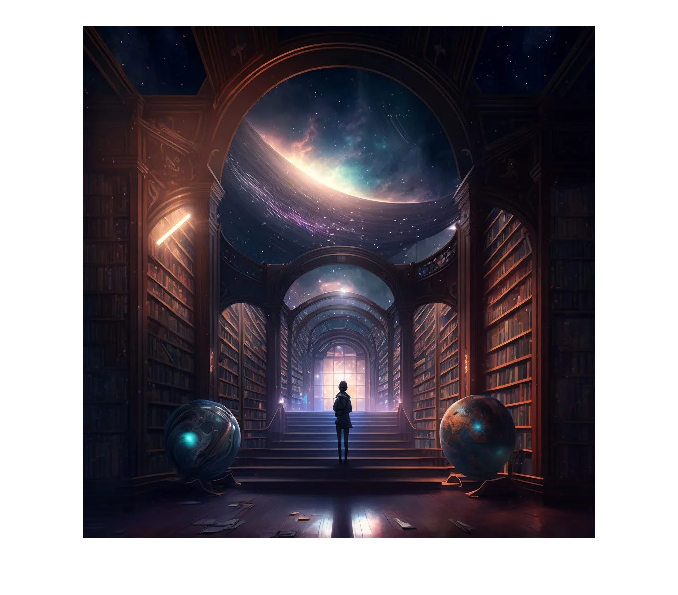

I = imread("1.tiff");
figure, imshow(I);

## Especificações da imagem no workspace

whos I;

  Name         Size                  Bytes  Class    Attributes

  I         1024x1024x3            3145728  uint8              



## Canal azul da imagem

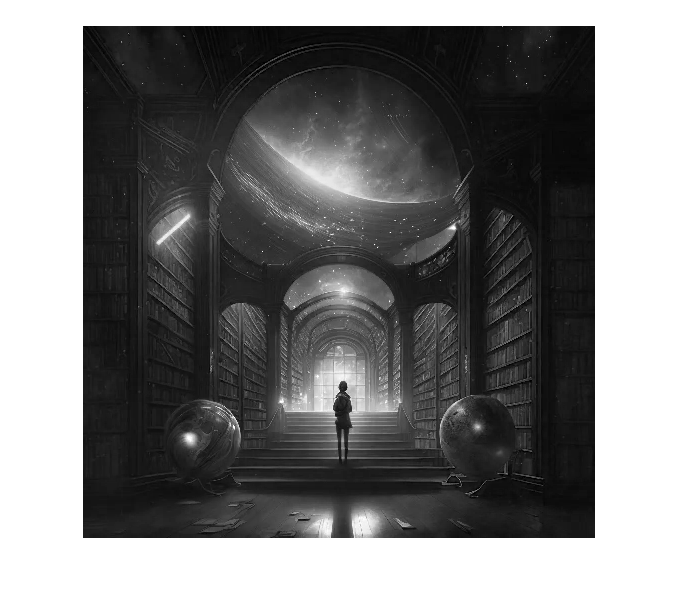

G = I(:,:,3);
figure, imshow(G);

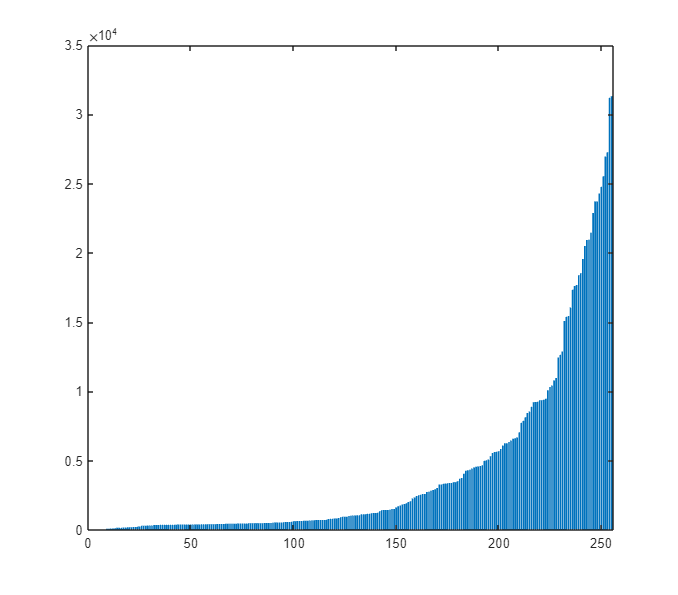

bar(sort(histogram(G).Values, 2))

## Histograma da imagem

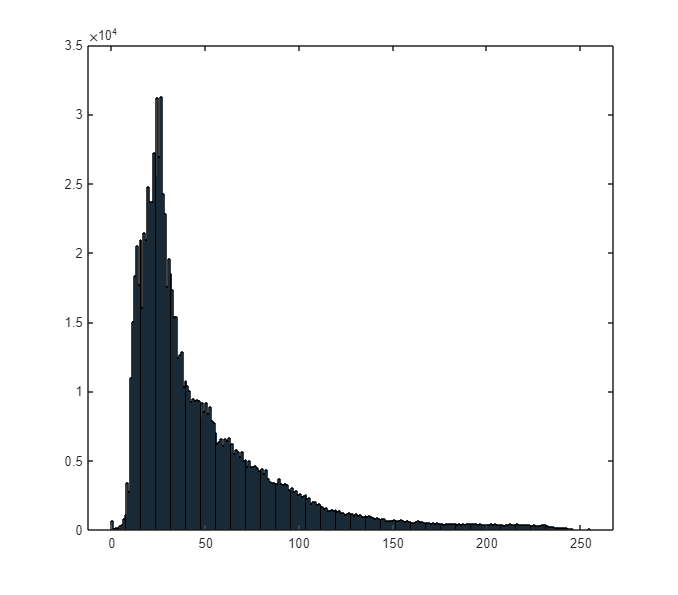

numofpixels = size(G, 1) * size(G, 2);
S = arrayfun(@(x, i) logs(x, i),sort(histogram(G).Values, 2), 1:255);

H = S / max(S) * 255

H =     0.0011    0.0047    0.0111    0.0202    0.0331    0.0541    0.0751    0.0997    0.1377    0.1721    0.2111    0.2668    0.3136    0.3759    0.4378    0.4987    0.5636    0.6421    0.7205    0.7998    0.8869    0.9822    1.0819    1.1987    1.3130    1.4616    1.5861    1.7067    1.8339    1.9636    2.1012    2.2770    2.4261    2.5839    2.7457    2.9101    3.0781    3.2482    3.4229    3.6039    3.7880    3.9785    4.1739    4.3778    4.5790    4.7848    4.9972    5.2144    5.4385    5.6723


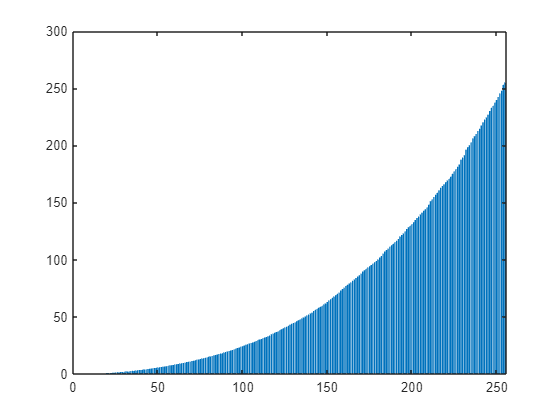

%H = histogram(G,'Normalization','cumcount').Values / numofpixels * 255;
figure, bar(H);

## Mostrar imagem com normalização do histograma

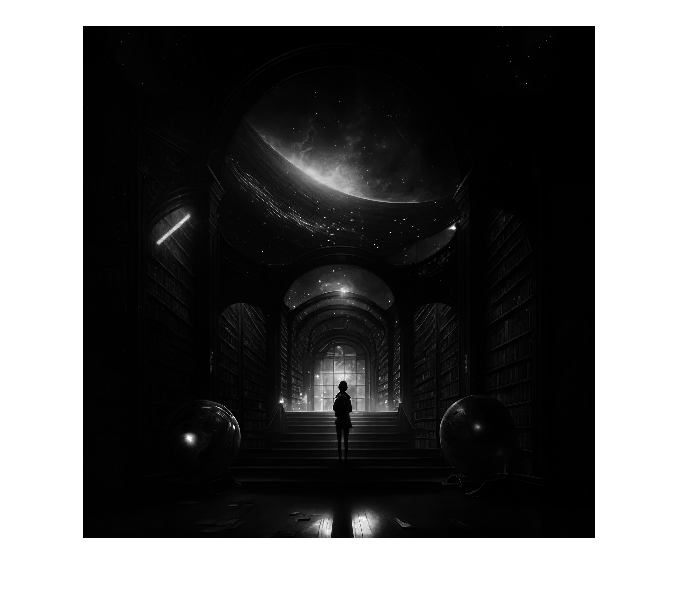

HI = aplicarHistograma(G, H);
figure, imshow(HI);

## Escrever imagem criada a partir do histograma no formato png

imwrite(HI, "1.png")

## Plotagem do gráfico da função tanh() * sin()

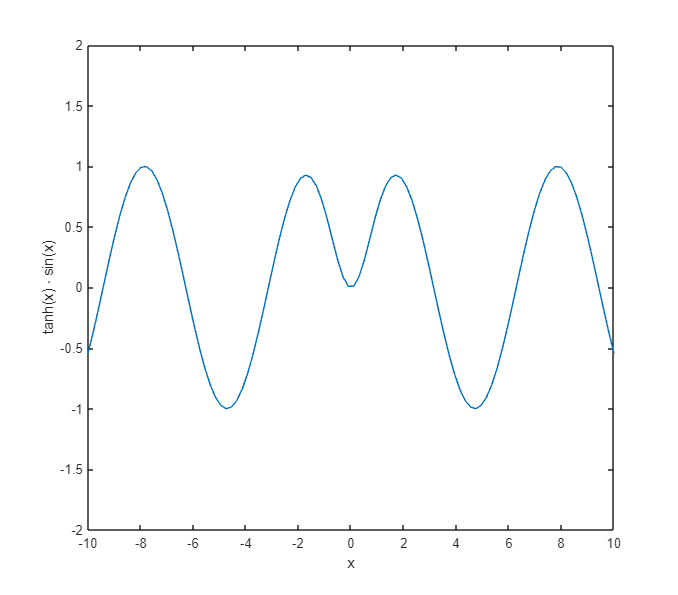

x = linspace(-10,10);
y = tanh(x) .* sin(x);

plot(x, y);
xlabel("x");
ylabel("tanh(x) ⋅ sin(x)")
ylim([-2,2]);

function y = logs(x, i)
    y = i*i * log2(x);
    if y < 0
        y = 0;
    end
end

## Função que aplica histograma na imagem

function HI = aplicarHistograma(I, H)
    HI = uint8(zeros(size(I,1), size(I,2)));
    % para cada linha da imagem
    for i = 1:size(I,1)
        % para cada coluna da imagem
        for j = 1:size(I,2)
            % atribui o valor correspondente do histograma
            HI(i,j) = H(I(i,j)+1);
        end
    end
end